# Structure From Motion of Castle Sequence

## Read the Input Image Sequence

Read and display the image sequence.

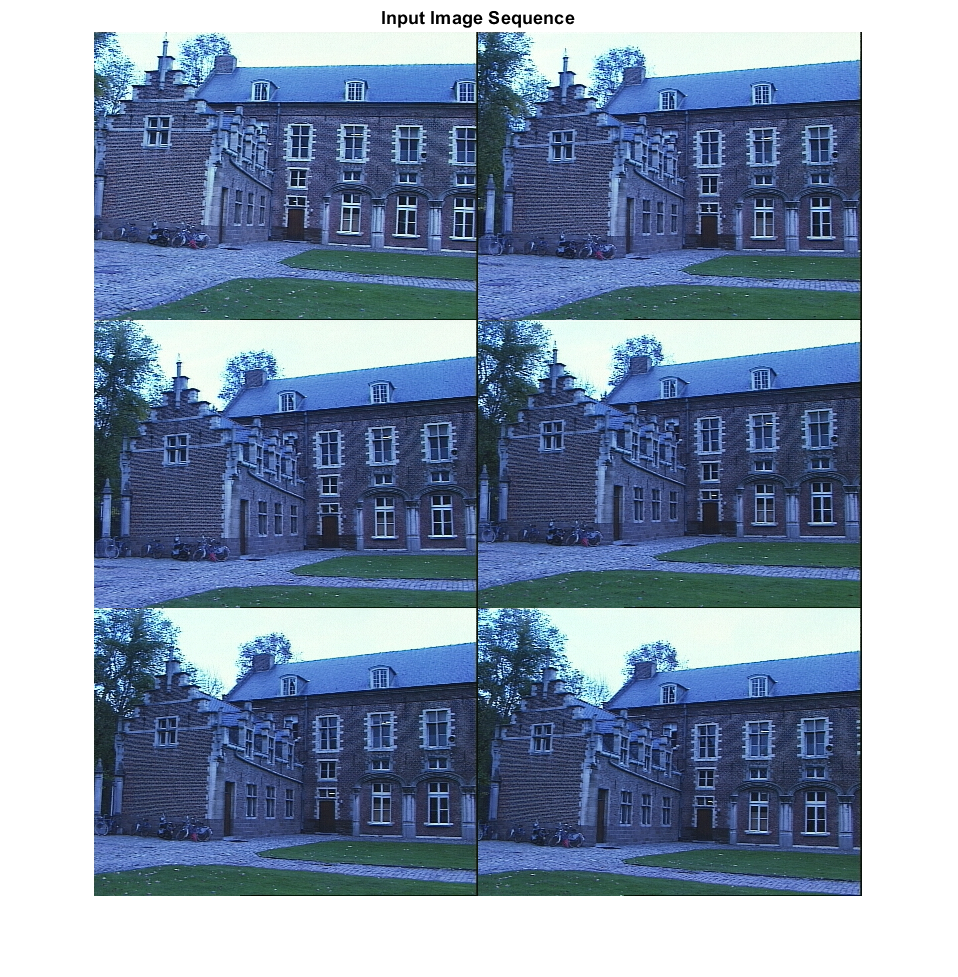

imds = imageDatastore('castlejpg');


% Display the images.
figure
montage(imds.Files, 'Size', [3, 2]);

% Convert the images to grayscale.
images = cell(1, numel(imds.Files));
for i = 1:numel(imds.Files)
    I = readimage(imds, i);
    images{i} = im2gray(I);
end

title('Input Image Sequence');

## Load Camera Parameters

Load the `cameraParameters` object created using the  [Camera Calibrator app](docid:vision_ref#burd_hd-1).

% Get intrinsic parameters of the camera
% intrinsics = cameraParams.Intrinsics;
focalLength    = [615 615];        % specified in units of pixels
principalPoint = [576/2 720/2];        % in pixels [x, y]
imageSize      = size(I,[1,2]); % in pixels [mrows, ncols]
intrinsics = cameraIntrinsics(focalLength, principalPoint, imageSize);

## Create a View Set Containing the First View

Use an [`imageviewset`](docid:vision_ref#mw_6e9e9e26-1c92-4289-a7d9-bccafaf79b78) object to store and manage the image points and the camera pose associated with each view, as well as point matches between pairs of views. Once you populate an [`imageviewset`](docid:vision_ref#mw_6e9e9e26-1c92-4289-a7d9-bccafaf79b78) object, you can use it to find point tracks across multiple views and retrieve the camera poses to be used by [`triangulateMultiview`](docid:vision_ref#bu4s48j-1) and [`bundleAdjustment`](docid:vision_ref#bu48f97-1) functions.

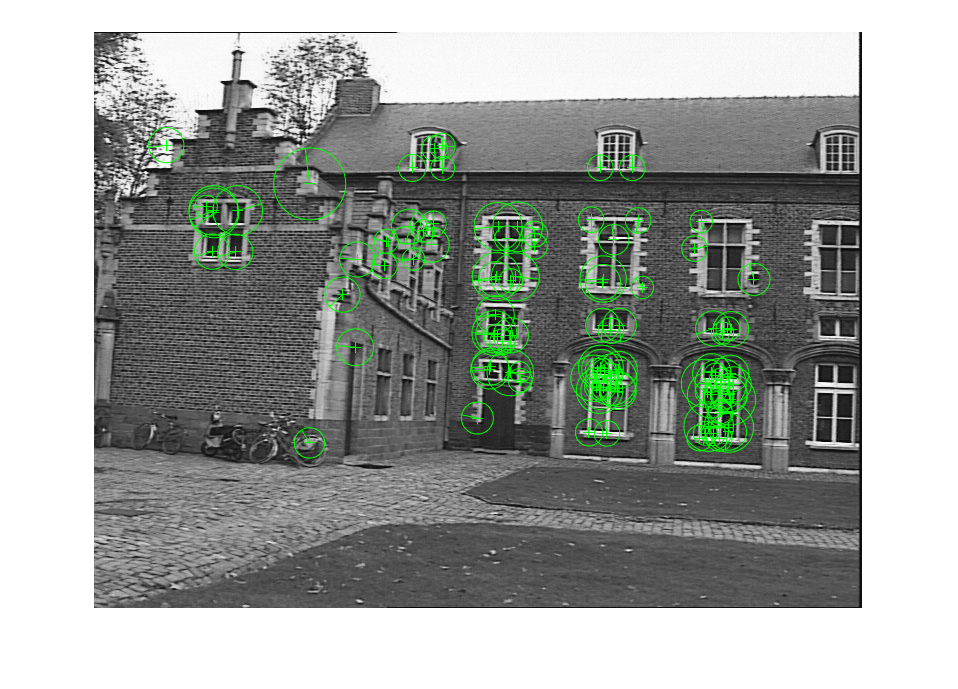

I = images{1};

% Detect features. Increasing 'NumOctaves' helps detect large-scale
% features in high-resolution images. Use an ROI to eliminate spurious
% features around the edges of the image.
border = 50;
roi = [border, 100, size(I, 2)- 2*border, size(I, 1)- 2*100];
prevPoints   = detectSURFFeatures(I, 'NumOctaves', 4, 'ROI', roi);

% Extract features. 
[prevFeatures,valid_points] = extractFeatures(I, prevPoints);
figure; imshow(I); hold on;
plot(valid_points.selectStrongest(100),'showOrientation',true);


% Create an empty imageviewset object to manage the data associated with each
% view.
vSet = imageviewset;

% Add the first view. Place the camera associated with the first view
% and the origin, oriented along the Z-axis.
viewId = 1;
vSet = addView(vSet, viewId, rigid3d, 'Points', prevPoints);

## Add the Rest of the Views

Go through the rest of the images. For each image

- Match points between the previous and the current image.

- Estimate the camera pose of the current view relative to the previous view.

- Compute the camera pose of the current view in the global coordinate system relative to the first view.

- Triangulate the initial 3-D world points.

- Use bundle adjustment to refine all camera poses and the 3-D world points.

for i = 2:numel(images)
% for i = 2:4
%     disp(string(i))
    I = images{i};
    
    % Detect, extract and match features.
    currPoints   = detectSURFFeatures(I, 'NumOctaves', 4, 'ROI', roi);


    currFeatures = extractFeatures(I, currPoints);    
    indexPairs   = matchFeatures(prevFeatures, currFeatures, ...
        'MaxRatio', .5, 'Unique',  true);
    
    % Select matched points.
    matchedPoints1 = prevPoints(indexPairs(:, 1));
    matchedPoints2 = currPoints(indexPairs(:, 2));
%     figure(i); 
%     showMatchedFeatures(images{i-1},I,matchedPoints1,matchedPoints2);

    % Estimate the camera pose of current view relative to the previous view.
    % The pose is computed up to scale, meaning that the distance between
    % the cameras in the previous view and the current view is set to 1.
    % This will be corrected by the bundle adjustment.
    [relativeOrient, relativeLoc, inlierIdx] = helperEstimateRelativePose(...
        matchedPoints1, matchedPoints2, intrinsics);
    
    % Get the table containing the previous camera pose.
    prevPose = poses(vSet, i-1).AbsolutePose;
    relPose  = rigid3d(relativeOrient(:,:,1), relativeLoc(1,:));
        
    % Compute the current camera pose in the global coordinate system 
    % relative to the first view.
    currPose = rigid3d(relPose.T * prevPose.T);
    
    % Add the current view to the view set.
    vSet = addView(vSet, i, currPose, 'Points', currPoints);

    % Store the point matches between the previous and the current views.
    vSet = addConnection(vSet, i-1, i, relPose, 'Matches', indexPairs(inlierIdx,:));
    
    % Find point tracks across all views.
    tracks = findTracks(vSet);

    % Get the table containing camera poses for all views.
    camPoses = poses(vSet);

    % Triangulate initial locations for the 3-D world points.
    xyzPoints = triangulateMultiview(tracks, camPoses, intrinsics);
    
    % Refine the 3-D world points and camera poses.
%     [xyzPoints, camPoses, reprojectionErrors] = bundleAdjustment(xyzPoints, ...
%         tracks, camPoses, intrinsics, 'FixedViewId', 1, ...
%         'PointsUndistorted', false,'Solver','preconditioned-conjugate-gradient');
    [xyzPoints, camPoses, reprojectionErrors] = bundleAdjustment(...
    xyzPoints, tracks, camPoses, intrinsics, 'FixedViewId', 1, ...
    'PointsUndistorted', true);

    % Store the refined camera poses.
    vSet = updateView(vSet, camPoses);

    prevFeatures = currFeatures;
    prevPoints   = currPoints;  
end

## Display Camera Poses

Display the refined camera poses and 3-D world points.

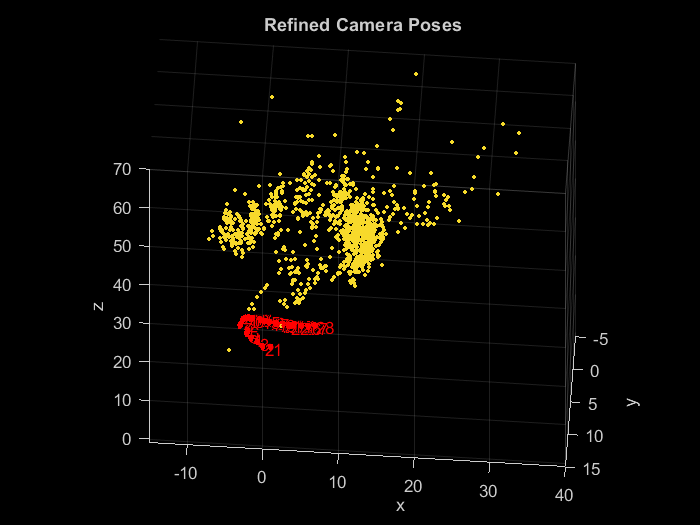

% Display camera poses.
camPoses = poses(vSet);
figure;
plotCamera(camPoses, 'Size', 0.2);
hold on

% Exclude noisy 3-D points.
goodIdx = find(reprojectionErrors < 0.5);
xyzPoints_good = xyzPoints(goodIdx, :);

% Display the 3-D points.
pcshow(xyzPoints_good, 'VerticalAxis', 'y', 'VerticalAxisDir', 'down', ...
    'MarkerSize', 45);
grid on
hold off

% Specify the viewing volume.
loc1 = camPoses.AbsolutePose(1).Translation;
xlim([loc1(1)-15, loc1(1)+40]);
ylim([loc1(2)-5, loc1(2)+15]);
zlim([loc1(3)-1, loc1(3)+70]);
camorbit(0, -30);
xlabel('x')
ylabel('y')
zlabel('z')
title('Refined Camera Poses');

## Compute Dense Reconstruction

Go through the images again. This time detect a dense set of corners, and track them across all views using[` vision.PointTracker`](docid:vision_ref#btghk3u-1).

% Read and undistort the first image
I = images{1};

% Detect corners in the first image.
% prevPoints = detectMinEigenFeatures(I, 'MinQuality', 0.001);
border = 50;
roi = [border, 100, size(I, 2)- 2*border, size(I, 1)- 2*100];
prevPoints   = detectSURFFeatures(I, 'NumOctaves', 4, 'ROI', roi);

% Extract features. Using 'Upright' features improves matching, as long as
% the camera motion involves little or no in-plane rotation.
% [prevFeatures,valid_points] = extractFeatures(I, prevPoints);
% figure; imshow(I); hold on;
% plot(valid_points.selectStrongest(100));

% Create the point tracker object to track the points across views.
tracker = vision.PointTracker('MaxBidirectionalError', 1, 'NumPyramidLevels', 4);

% Initialize the point tracker.
prevPoints = prevPoints.Location;
initialize(tracker, prevPoints, I);

% Store the dense points in the view set.

vSet = updateConnection(vSet, 1, 2, 'Matches', zeros(0, 2));
vSet = updateView(vSet, 1, 'Points', prevPoints);

% Track the points across all views.
for i = 2:numel(images)
    % Read and undistort the current image.
    I = undistortImage(images{i}, intrinsics); 
    
    % Track the points.
    [currPoints, validIdx] = step(tracker, I);
    
    % Clear the old matches between the points.
    if i < numel(images)
        vSet = updateConnection(vSet, i, i+1, 'Matches', zeros(0, 2));
    end
    vSet = updateView(vSet, i, 'Points', currPoints);
    
    % Store the point matches in the view set.
    matches = repmat((1:size(prevPoints, 1))', [1, 2]);
    matches = matches(validIdx, :);        
    vSet = updateConnection(vSet, i-1, i, 'Matches', matches);
end

% Find point tracks across all views.
tracks = findTracks(vSet);

% Find point tracks across all views.
camPoses = poses(vSet);

% Triangulate initial locations for the 3-D world points.
xyzPoints = triangulateMultiview(tracks, camPoses,...
    intrinsics);

% Refine the 3-D world points and camera poses.
[xyzPoints, camPoses, reprojectionErrors] = bundleAdjustment(...
    xyzPoints, tracks, camPoses, intrinsics, 'FixedViewId', 1, ...
    'PointsUndistorted', false);

## Display Dense Reconstruction

Display the camera poses and the dense point cloud.

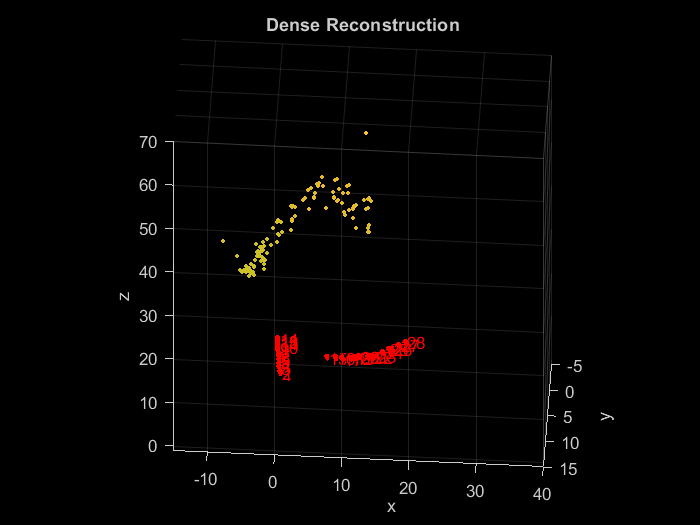

% Display the refined camera poses.
figure;
plotCamera(camPoses, 'Size', 0.2);
hold on

% Exclude noisy 3-D world points.
goodIdx = find(reprojectionErrors < 2);

% Display the dense 3-D world points.
pcshow(xyzPoints(goodIdx, :), 'VerticalAxis', 'y', 'VerticalAxisDir', 'down', ...
    'MarkerSize', 45);
grid on
hold off

% Specify the viewing volume.
loc1 = camPoses.AbsolutePose(1).Translation;
xlim([loc1(1)-15, loc1(1)+40]);
ylim([loc1(2)-5, loc1(2)+15]);
zlim([loc1(3)-1, loc1(3)+70]);
camorbit(0, -30);
xlabel('x')
ylabel('y')
zlabel('z')

title('Dense Reconstruction');

## References

Based from [Structure From Motion From Multiple Views - MATLAB & Simulink (mathworks.com)](https://www.mathworks.com/help/vision/ug/structure-from-motion-from-multiple-views.html)

[1] M.I.A. Lourakis and A.A. Argyros (2009). "SBA: A Software Package for Generic Sparse Bundle Adjustment". ACM Transactions on Mathematical Software (ACM) 36 (1): 1-30.

[2] R. Hartley, A. Zisserman, "Multiple View Geometry in Computer Vision," Cambridge University Press, 2003.

[3] B. Triggs; P. McLauchlan; R. Hartley; A. Fitzgibbon (1999). "Bundle Adjustment: A Modern Synthesis". Proceedings of the International Workshop on Vision Algorithms. Springer-Verlag. pp. 298-372.

*Copyright 2015 The MathWorks, Inc.*